
ex1 = 'example1.dat'

ex1 = 'example1.dat'

ex2 = 'example1.dat'

ex2 = 'example1.dat'



E = csvread('example1.dat')

E =      1     2
     1     3
     1     4
     1     5
     1     6
     1     7
     8     9
     8    10
     8     5
     8    11



% Algo

%1, Form A with A_ij = exp(-abs(s_i-s_s)^2/2sig^2) if i!=j and A_ii = 0
%2, definde D diagnonal matrix with (i,i) element sum of A's iith row and L
%2b, L = D^(-1/2)AD^(1/2)
%3 find X with k eignvectors form L and for X
%4 For the matrix Y from X by renomalizing Xs ros to have unit len
%5 TReat every row in Y as a point in R^k and use K clusters with K-means
% assign the orignal point s_i to cluster j if and only if Y is asigned toj

k = 4

k = 4

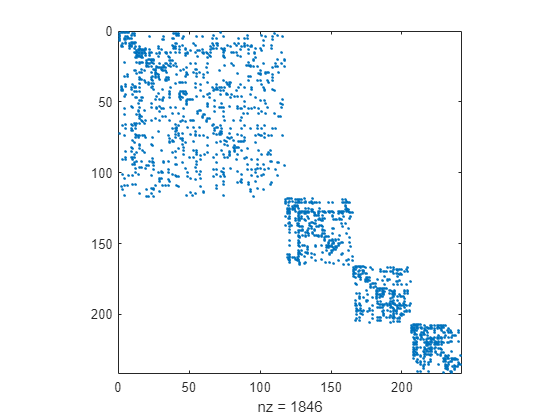


% 1 from canvas
col1 = E(:,1);
col2 = E(:,2);

max_ids = max(max(col1,col2));
As= sparse(col1, col2, 1, max_ids, max_ids); 
A = full(As);

spy(A)

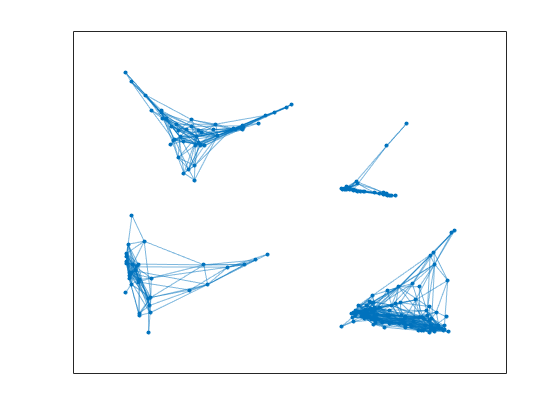


plot(graph(A));

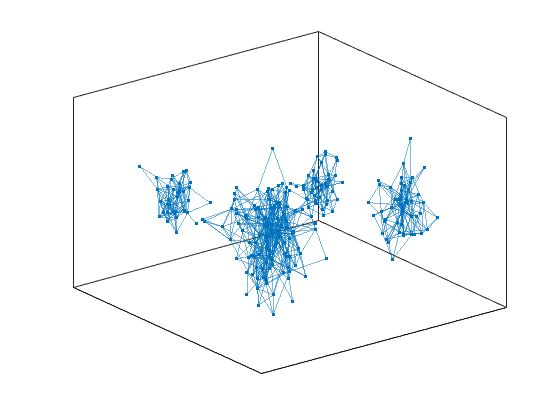


plot(graph(A),'Layout','force3')

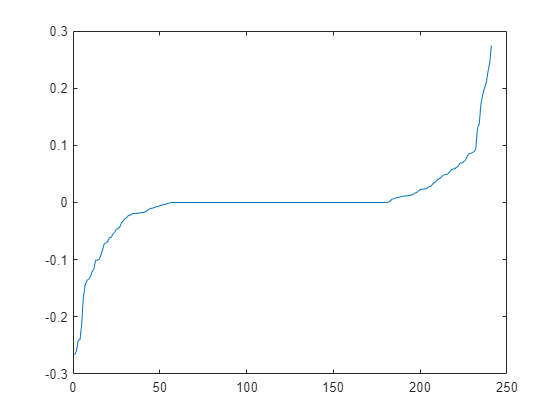


%2
D=diag(sum(A,2));

L=(D^(-1/2)*A*D^(-1/2));

%3
[V,D] = eigs(L,k); %A

%4
Y= V./sum(V.*V,2).^(1/2);

%5
clust = kmeans(Y,k);

[F_V,~]=eigs(L,2,'SA');
ordered = sort(F_V(:,2));

plot(ordered)